# ME 419 Lab 1

**Names:** Julia Fay, Aiden Taylor 

**Date:** 2024.1.11

**Class:** ME419

**Description: **The purpose of this file is to simulate various first and second order mechanical systems using simulink.

## Exercise 1

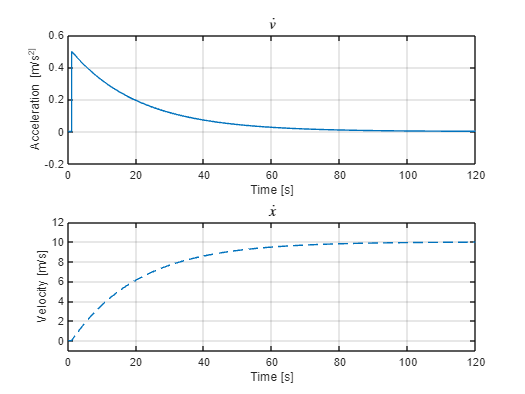

subplot (2,1,1);            %start the subplot
x = sim('Lab1_419_simul');  %run simulink simulation
plot(x.tout, x.simout(:,1));%plot acceleration
grid on;
title('$\dot{v}$', 'Interpreter', 'latex','FontSize',12,'FontWeight','bold')  
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')
axis([0 120 -0.2 0.6])
subplot(2,1,2);             %plot velocity
plot(x.tout, x.simout(:,2), '--')
grid on;
title("$\dot{x}$", 'Interpreter', 'latex','FontSize',12,'FontWeight','bold');
xlabel('Time [s]')
ylabel('Velocity [m/s]')
axis([0 120 -1 12])

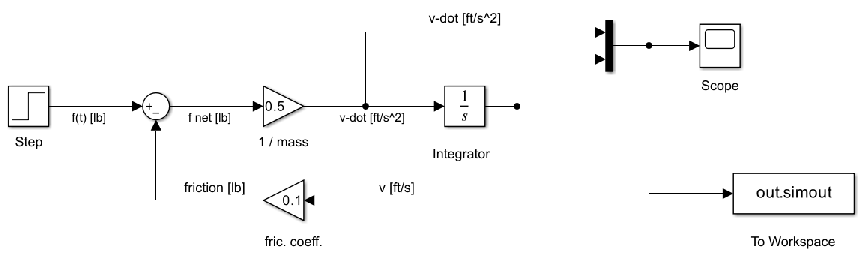

snapshotModel('Lab1_419_simul') %output simulink image

## Exercise 2

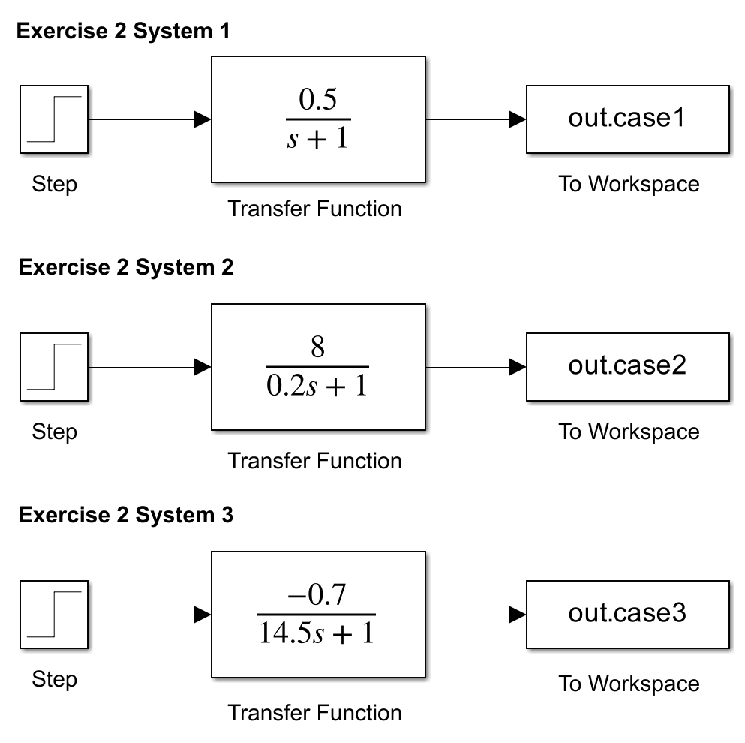

%run the block diagram 
run = sim("Lab1_Exercise2_BD.slx");

%import the block diagram image 
snapshotModel('Lab1_Exercise2_BD') 


%create a tiled layout 
fig1 = figure();
tl = tiledlayout(3,1);         
title(tl,'Exercise 2','FontSize',12,'FontWeight','bold');
fig1.Position(3:4) = [560*3 420*5]; %scale subplot

%plot the results for case 1 and format
nexttile; 
plot(run.tout,run.case1)
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 10 -0.1 0.6]);
title('System One','FontSize',10,'FontWeight','bold');
grid on

%case 2
%plot the results for case 2 and format
nexttile; 
plot(run.tout,run.case2)
yline(run.case2(158), 'red')
xline(1, 'magenta')
yline(0, 'red')
xline(run.tout(6), 'magenta')
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 10 -1 9]);
title('Tank System Two with a Steady State gain of 8 and Settling time of 0.8 s','FontSize',10,'FontWeight','bold');
legend('Response', 'Gain', 'Time Constant', 'Location', 'southeast')
grid on

%case 3
%plot the results for case 3 and format
nexttile;
plot(run.tout,run.case3)
yline(run.case3(158), 'red')
run.case3(158)

ans = -0.6992

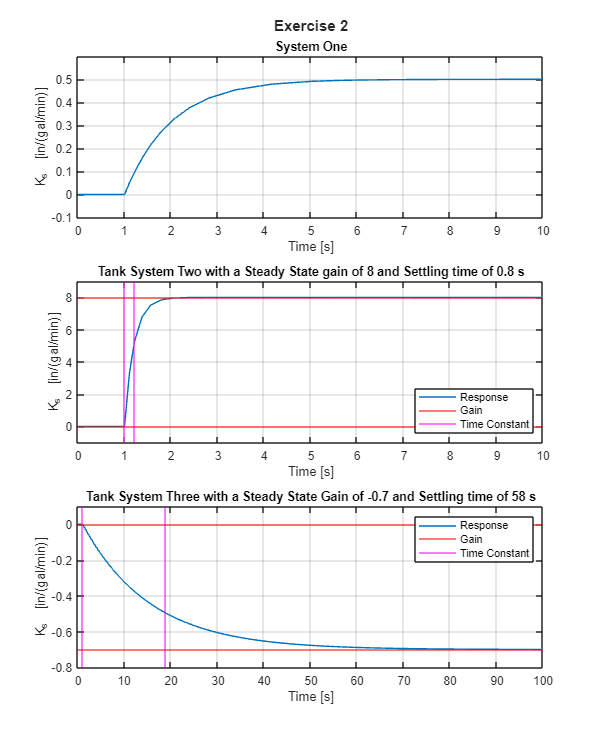

xline(1, 'magenta')
yline(0, 'red')
xline(run.tout(36), 'magenta')
xlabel("Time [s]");
ylabel("K_s  [in/(gal/min)]");
axis([0 100 -0.8 0.1]);
title('Tank System Three with a Steady State Gain of -0.7 and Settling time of 58 s','FontSize',10,'FontWeight','bold');
legend('Response', 'Gain', 'Time Constant', 'Location', 'northeast')
grid on

## Exercise 3

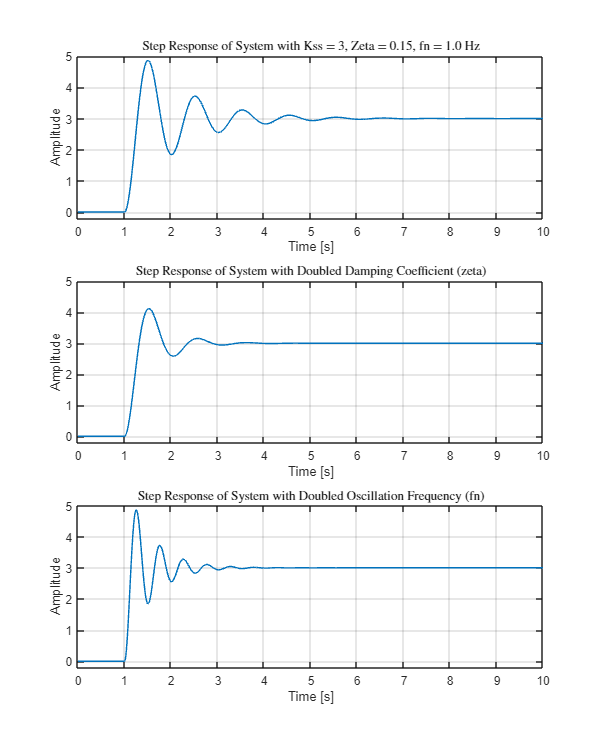

fig1 = figure();
fig1.Position(3:4) = [560*3 420*5]; %scale subplot
y = sim('Lab1_419_simul3');         %run simulink
subplot (3,1,1);                    %plot sys 1
plot(y.tout, y.simout(:,1));
grid on;
title('Step Response of System with Kss = 3, Zeta = 0.15, fn = 1.0 Hz', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

subplot(3,1,2);                     %plot sys 2
plot(y.tout, y.simout1(:,1));
grid on;
title('Step Response of System with Doubled Damping Coefficient (zeta)', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

subplot(3,1,3);                     %plot sys 3
plot(y.tout, y.simout2(:,1));
grid on;
title('Step Response of System with Doubled Oscillation Frequency (fn)', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])

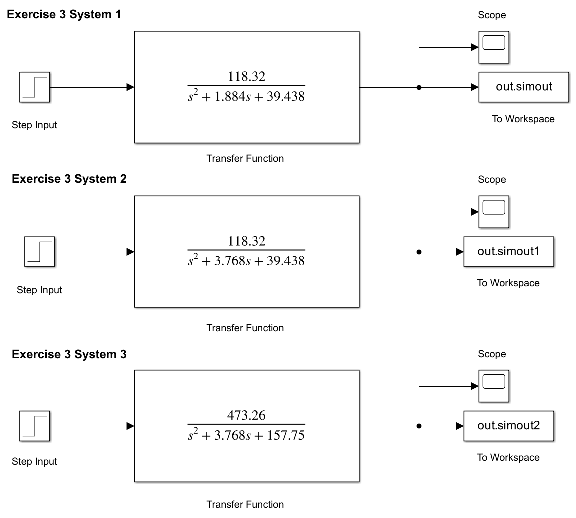

snapshotModel('Lab1_419_simul3')

## Exercise 4

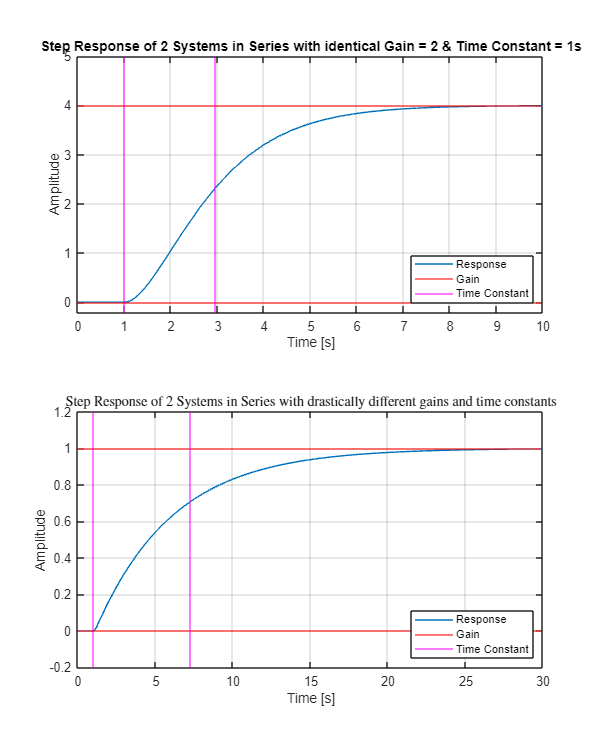

fig1 = figure();
fig1.Position(3:4) = [560*3 420*5]; %scale subplot
z = sim('Lab1_419_simul4');         %run simulink
subplot (2,1,1);                    %plot sys 1
plot(z.tout, z.simout(:,1));
hold on
yline(z.simout(98), 'red')
xline(1, 'magenta')
yline(0, 'red')
xline(z.simout(18), 'magenta')
grid on;
title('Step Response of 2 Systems in Series with identical Gain = 2 & Time Constant = 1s', 'Interpreter', 'latex')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 10 -0.2 5])
legend('Response', 'Gain', 'Time Constant', 'Location', 'southeast')
hold off
subplot (2,1,2);                    %plot sys 1
plot(z.tout, z.simout1(:,1));
hold on
yline(z.simout1(98), 'red')
xline(1, 'magenta')
yline(0, 'red')
xline(z.tout(29), 'magenta')
grid on;
title('Step Response of 2 Systems in Series with drastically different gains and time constants', 'Interpreter', 'latex')
legend('Response', 'Gain', 'Time Constant', 'Location', 'southeast')
xlabel('Time [s]')
ylabel('Amplitude')
axis([0 30 -0.2 1.2])
hold off

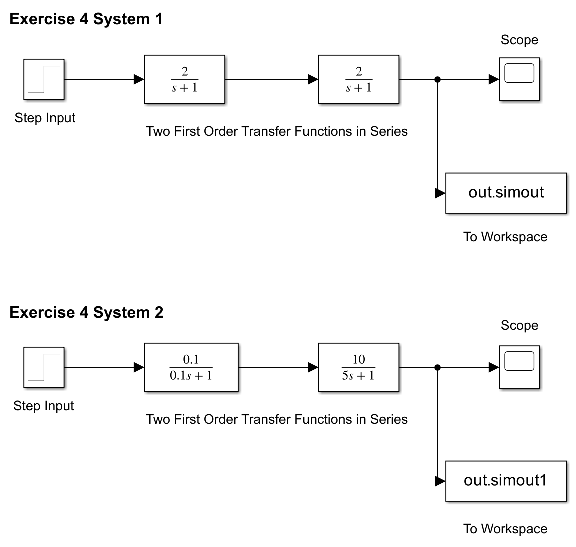

snapshotModel('Lab1_419_simul4')

## Exercise 5

%run the block diagram 
run5 = sim("Lab1_419_sim5.slx");

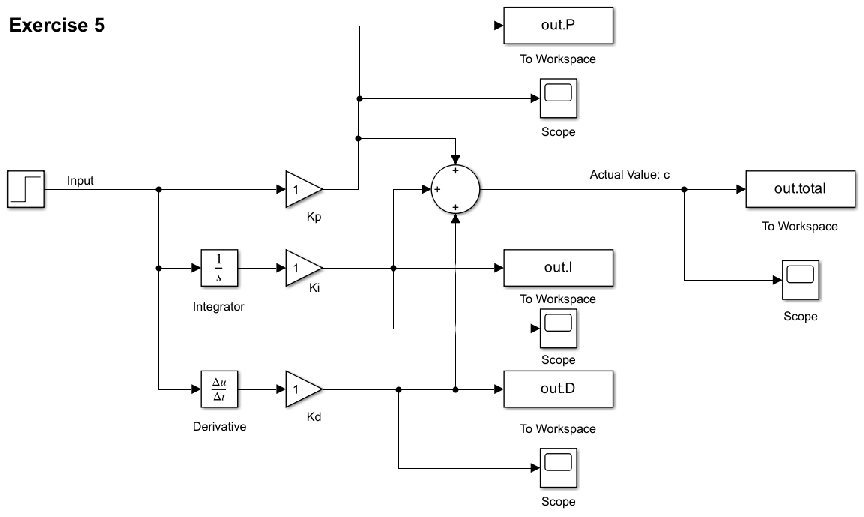


%import the block diagram image 
snapshotModel('Lab1_419_sim5') 

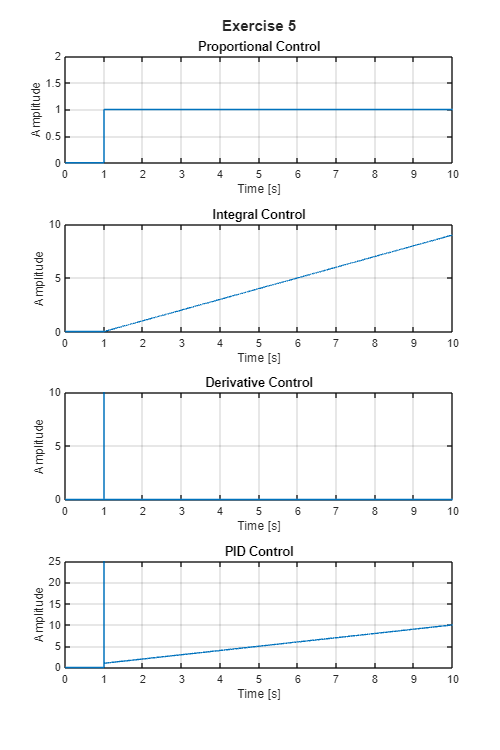


%create a tiled layout 
fig5 = figure();
t5 = tiledlayout(4,1);         
title(t5,'Exercise 5','FontSize',12,'FontWeight','bold');
fig5.Position(3:4) = [560*3 420*6]; %scale subplot

%plot the results for Proportional Control and format
nexttile; 
plot(run5.tout,run5.P)
xlabel("Time [s]");
ylabel("Amplitude");
axis([0 10 0 2]);
title('Proportional Control','FontSize',10,'FontWeight','bold');
grid on

%plot the results for Integral Control and format
nexttile; 
plot(run5.tout,run5.I)
xlabel("Time [s]");
ylabel("Amplitude");
axis([0 10 0 10]);
title('Integral Control','FontSize',10,'FontWeight','bold');
grid on

%plot the results for Derivative Control and format
nexttile; 
plot(run5.tout,run5.D)
xlabel("Time [s]");
ylabel("Amplitude");
axis([0 10 0 10]);
title('Derivative Control','FontSize',10,'FontWeight','bold');
grid on

%plot the results for Total Control and format
nexttile; 
plot(run5.tout,run5.total)
xlabel("Time [s]");
ylabel("Amplitude");
axis([0 10 0 25]);
title('PID Control','FontSize',10,'FontWeight','bold');
grid on

## Exercise 6

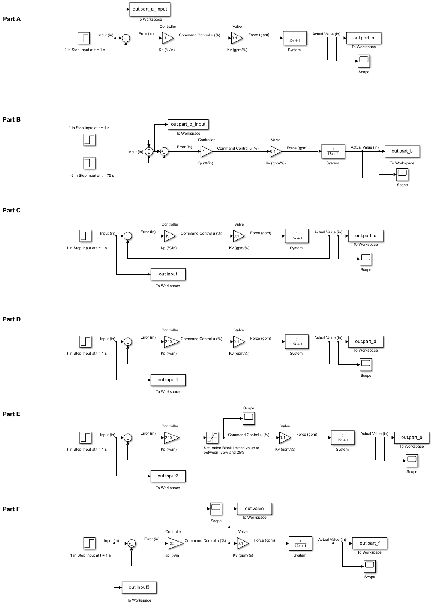

%run the block diagram 
run6 = sim("Lab1_419_sim6.slx");

%import the block diagram image 
snapshotModel('Lab1_419_sim6') 

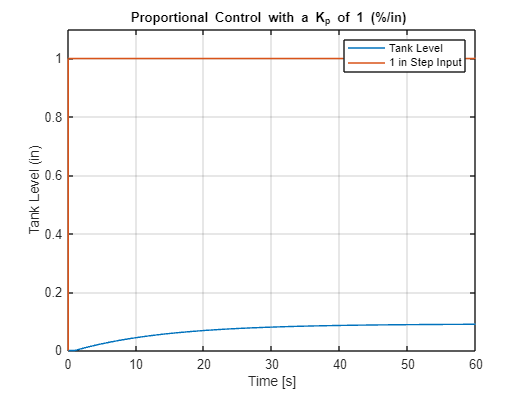

c = newline; %create a newline character 

%PART A
fig6a = figure();
plot(run6.tout,run6.part_a)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.1]);
title('Proportional Control with a K_p of 1 (%/in) ','FontSize',10,'FontWeight','bold');
grid on
hold on 
plot(run6.tout(1:101),run6.part_a_input)
legend('Tank Level','1 in Step Input','Location','northeast')

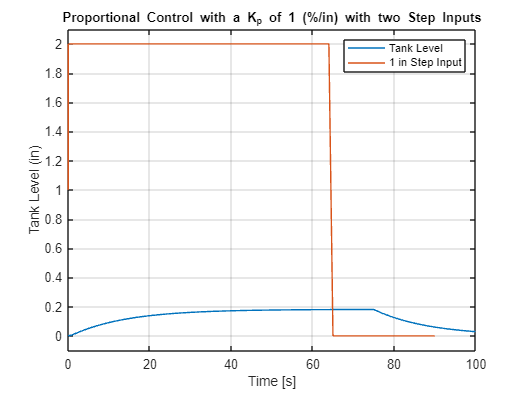



%PART B
fig6b = figure(); 
plot(run6.tout,run6.part_b)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 100 -0.1 2.1]);
title('Proportional Control with a K_p of 1 (%/in) with two Step Inputs','FontSize',10,'FontWeight','bold');
grid on
hold on 
plot(run6.tout(1:101),run6.part_b_input)
legend('Tank Level','1 in Step Input','Location','northeast')

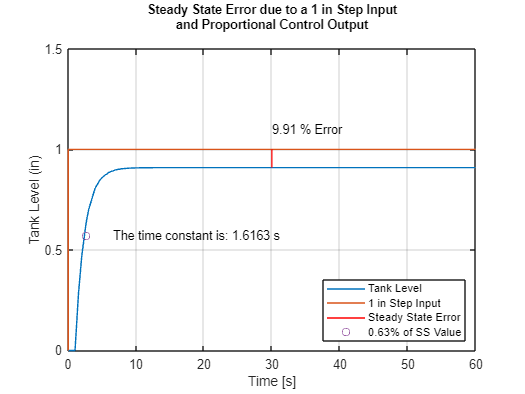


%PART C
fig6c = figure(); 
plot(run6.tout,run6.part_c)
hold on 
fix = [run6.input;1;1;1;1;1;1;1;1;1;1];
plot(run6.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
c6 = "Steady State Error due to a 1 in Step Input" + newline +"and Proportional Control Output" + newline;
title(c6,'FontSize',10,'FontWeight','bold');
grid on

%add legend, show percent error and time constant on the plot 
c6ss = run6.part_c(101);
c6x = [30 30];
c6y = [c6ss 1];
c6line = line(c6x,c6y,'Color','red');
c6text = text(30, 1.1,'9.91 % Error');
%find time constant 
c6_63 = c6ss*0.63;
c6_pos = 9;
c6_tau = run6.tout(c6_pos)-1;
plot(c6_tau+1,c6_63,'o');
c6m = "The time constant is: " + num2str(c6_tau) + " s";
text(c6_tau+5,c6_63,c6m);
legend('Tank Level','1 in Step Input','Steady State Error','0.63% of SS Value','Location','southeast')

%PART D 
fig6d = figure();  
plot(run6.tout,run6.part_d)
hold on 
plot(run6.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
dtitle6 = ['Steady State Error due to a 1 in Step Input and Proportional Control Output' newline 'with a Modified Gain to Produce a Time Constant Less than 1 s' newline];
title(dtitle6,'FontSize',10,'FontWeight','bold');
grid on
%add legend, show percent error and time constant on the plot 
d6ss = run6.part_d(101);
d6x = [30 30];
d6y = [d6ss 1];
d6line = line(d6x,d6y,'Color','red');
d6text = text(30, 1.1,'4.76 % Error');
%find time constant 
d6_63 = d6ss*0.63;
d6_pos = 8; %change
d6_tau = run6.tout(d6_pos)-1;
plot(d6_tau+1,d6_63,'o');
d6m = "The time constant is: " + num2str(d6_tau) + " s";
text(d6_tau+5,d6_63,d6m);
legend('Tank Level','1 in Step Input','Steady State Error','0.63% of SS Value','Location','southeast')
d_ans = "The steady state error dictates the controller " + newline +"gain because it is responsible for the steady state" + newline + "value the system reaches, which is used to calculate the error."

d_ans =     "The steady state error dictates the controller 
     gain because it is responsible for the steady state
     value the system reaches, which is used to calculate the error."


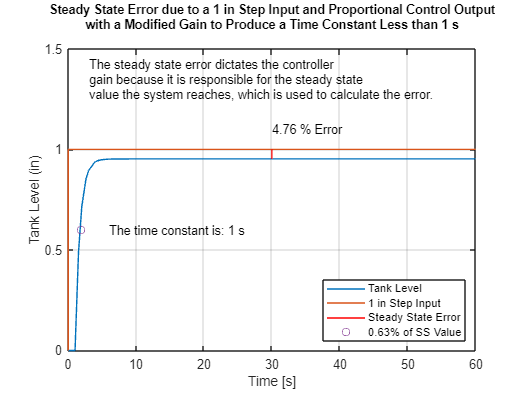

text(3, 1.35, d_ans)

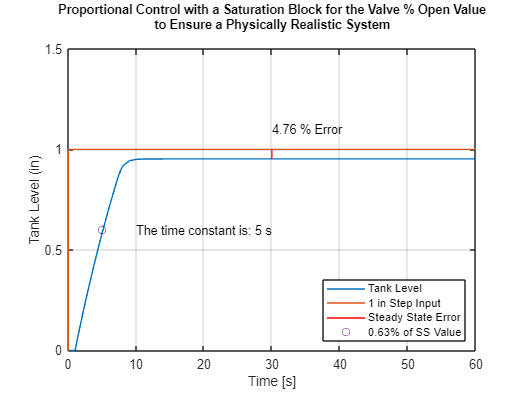

%PART E 
fig6e = figure();  
plot(run6.tout,run6.part_e)
hold on 
plot(run6.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
etitle6 = ['Proportional Control with a Saturation Block for the Valve % Open Value' newline 'to Ensure a Physically Realistic System' newline];
title(etitle6,'FontSize',10,'FontWeight','bold');
grid on
legend('Tank Level','1 in Step Input','Location','southeast')
%add legend, show percent error and time constant on the plot 
e6ss = run6.part_e(101);
e6x = [30 30];
e6y = [e6ss 1];
e6line = line(e6x,e6y,'Color','red');
e6text = text(30, 1.1,'4.76 % Error');
%find time constant 
e6_63 = e6ss*0.63;
e6_pos = 15; %change
e6_tau = run6.tout(e6_pos)-1;
plot(e6_tau,e6_63,'o');
e6m = "The time constant is: " + num2str(e6_tau) + " s";
text(e6_tau+5,e6_63,e6m);
legend('Tank Level','1 in Step Input','Steady State Error','0.63% of SS Value','Location','southeast')

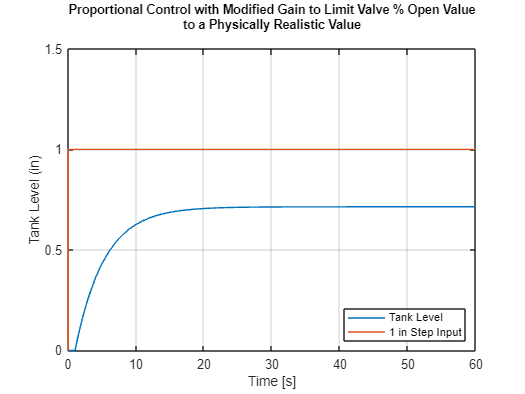


%PART F 
fig6f = figure(); 
plot(run6.tout,run6.part_f)
hold on 
plot(run6.tout,fix)
xlabel("Time [s]");
ylabel("Tank Level (in)");
axis([0 60 0 1.5]);
ftitle6 = ['Proportional Control with Modified Gain to Limit Valve % Open Value' newline 'to a Physically Realistic Value' newline];
title(ftitle6,'FontSize',10,'FontWeight','bold');
grid on
legend('Tank Level','1 in Step Input','Location','southeast')

## Exercise 7

%run the block diagram 
desired = 20 %get the absolute desired tank level from the user

desired = 20

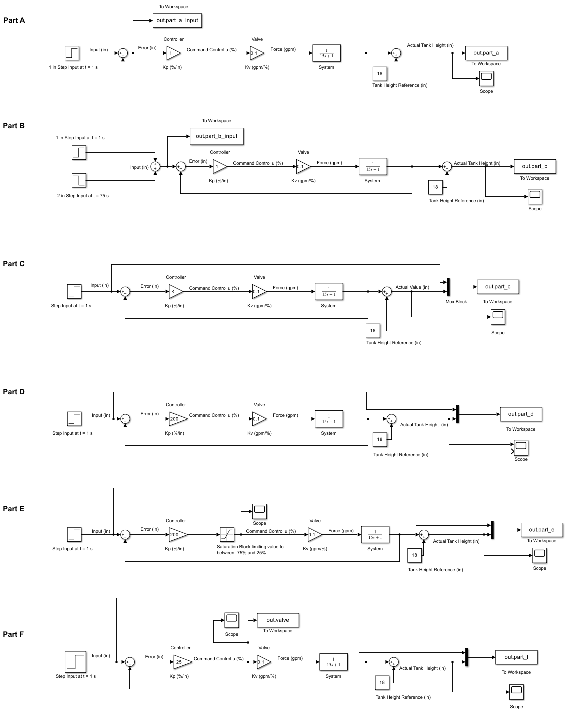


run7 = sim("Lab1_419_sim7.slx");

%import the block diagram image 
snapshotModel('Lab1_419_sim7') 

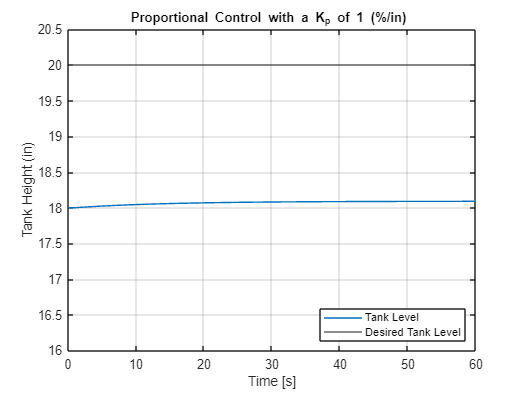

%PART A
% nexttile; 
fig7a = figure();
plot(run7.tout,run7.part_a)
xlabel("Time [s]");
ylabel("Tank Height (in)");
axis([0 60 16 20.5]);
title('Proportional Control with a K_p of 1 (%/in) ','FontSize',10,'FontWeight','bold');
grid on
hold on 
yline(desired)
legend('Tank Level', 'Desired Tank Level','Location','southeast')

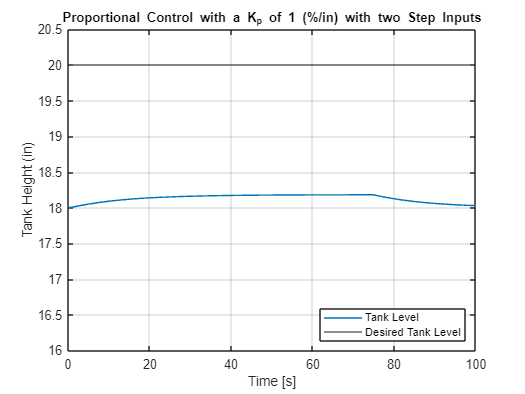



%PART B
% nexttile; 
fig7b = figure();
plot(run7.tout,run7.part_b)
xlabel("Time [s]");
ylabel("Tank Height (in)");
axis([0 100 16 20.5]);
title('Proportional Control with a K_p of 1 (%/in) with two Step Inputs','FontSize',10,'FontWeight','bold');
grid on
hold on 
yline(desired)
legend('Tank Level', 'Desired Tank Level','Location','southeast')

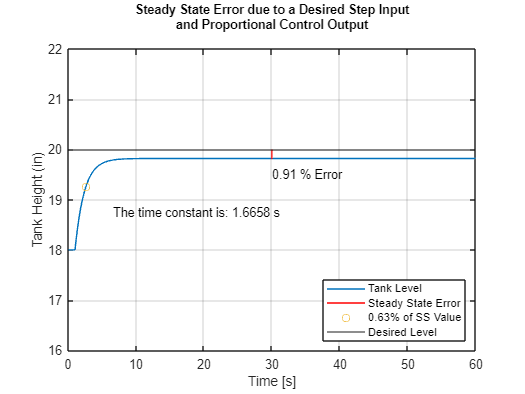



%PART C
% nexttile; 
fig7c = figure();
plot(run7.tout,run7.part_c(:,2))
hold on 
yline(desired)
xlabel("Time [s]");
ylabel("Tank Height (in)");
axis([0 60 16 22]);
c7 = "Steady State Error due to a Desired Step Input" + newline +"and Proportional Control Output" + newline;
title(c7,'FontSize',10,'FontWeight','bold');
grid on

%add legend, show percent error and time constant on the plot 
c7ss = run7.part_c(101,2);
c7x = [30 30];
c7y = [c7ss 20];
c7line = line(c7x,c7y,'Color','red');
c7text = text(30, 19.5,'0.91 % Error');
%find time constant 
c7_63 = 2*0.63;
c7_pos = 52; %change
c7_tau = run7.tout(c7_pos)-1;
plot(c7_tau+1,c7_63+18,'o');
c7m = "The time constant is: " + num2str(c7_tau) + " s";
text(c7_tau+5,c7_63+17.5,c7m);
legend('Tank Level','Desired Level','Steady State Error','0.63% of SS Value','Location','southeast')

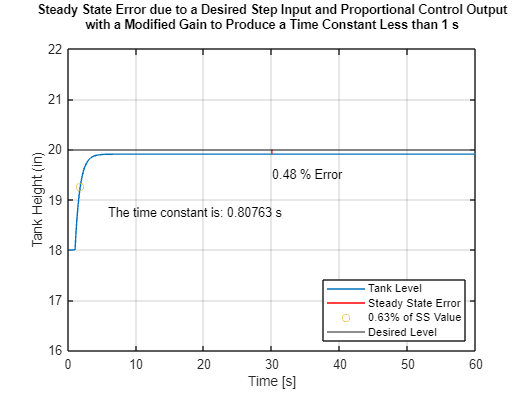



%PART D 
% nexttile;
fig7d = figure();
plot(run7.tout,run7.part_d(:,2))
hold on 
yline(desired)
xlabel("Time [s]");
ylabel("Tank Height (in)");
axis([0 60 16 22]);
dtitle7 = ['Steady State Error due to a Desired Step Input and Proportional Control Output' newline 'with a Modified Gain to Produce a Time Constant Less than 1 s' newline];
title(dtitle7,'FontSize',10,'FontWeight','bold');
grid on
legend('Tank Level', 'Desired Level', 'Location','southeast')
%add legend, show percent error and time constant on the plot 
d7ss = run7.part_d(101,2);
d7x = [30 30];
d7y = [d7ss 20];
d7line = line(d7x,d7y,'Color','red');
d7text = text(30, 19.5,'0.48 % Error');
%find time constant 
d7_63 = 2*0.63;
d7_pos = 34; %change
d7_tau = run7.tout(d7_pos)-1;
plot(d7_tau+1,d7_63+18,'o');
d7m = "The time constant is: " + num2str(d7_tau) + " s";
text(d7_tau+5,d7_63+17.5,d7m);
legend('Tank Level','Desired Level','Steady State Error','0.63% of SS Value','Location','southeast')

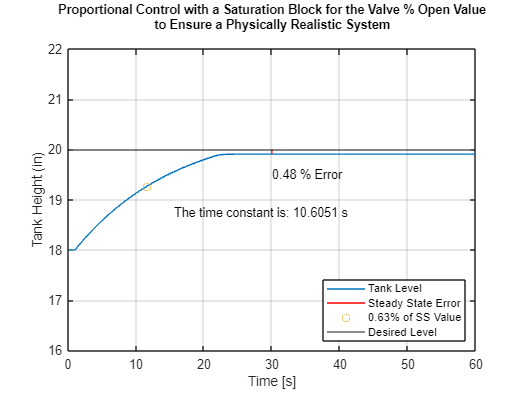



%PART E 
% nexttile;
fig7e = figure();
plot(run7.tout,run7.part_e(:,2))
hold on 
yline(desired)
xlabel("Time [s]");
ylabel("Tank Height (in)");
axis([0 60 16 22]);
etitle7 = ['Proportional Control with a Saturation Block for the Valve % Open Value' newline 'to Ensure a Physically Realistic System' newline];
title(etitle7,'FontSize',10,'FontWeight','bold');
grid on
%add legend, show percent error and time constant on the plot 
e7ss = 19.9048;
e7x = [30 30];
e7y = [e7ss 20];
e7line = line(e7x,e7y,'Color','red');
e7text = text(30, 19.5,'0.48 % Error');
%find time constant 
e7_63 = 2*0.63;
e7_pos = 120; %change
e7_tau = run7.tout(e7_pos)-1;
plot(e7_tau+1,e7_63+18,'o');
e7m = "The time constant is: " + num2str(e7_tau) + " s";
text(e7_tau+5,e7_63+17.5,e7m);
legend('Tank Level','Desired Level','Steady State Error','0.63% of SS Value','Location','southeast')

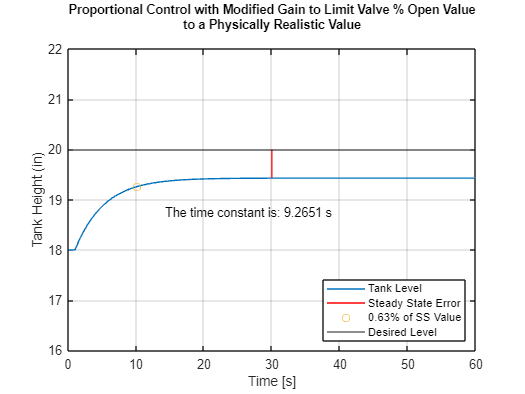



%PART F 
% nexttile; 
fig7f = figure();
plot(run7.tout,run7.part_f(:,2))
hold on 
yline(desired)
xlabel("Time [s]");
ylabel("Tank Height (in)");
axis([0 60 16 22]);
ftitle7 = ['Proportional Control with Modified Gain to Limit Valve % Open Value' newline 'to a Physically Realistic Value' newline];
title(ftitle7,'FontSize',10,'FontWeight','bold');
grid on

%add legend, show percent error and time constant on the plot 
f7ss = run7.part_f(454,2);
f7x = [30 30];
f7y = [f7ss 20];
f7line = line(f7x,f7y,'Color','red');
f7text = text(30, 1.1,'2.86 % Error');
%find time constant 
f7_63 = 2*0.63 ;
f7_pos = 115; %change
f7_tau = run7.tout(f7_pos)-1;
plot(f7_tau+1,f7_63+18,'o');
f7m = "The time constant is: " + num2str(f7_tau) + " s";
text(f7_tau+5,f7_63+17.5,f7m);
legend('Tank Level','Desired Level','Steady State Error','0.63% of SS Value','Location','southeast')

## Exercise 8

run8 = sim('Lab1_419_sim8');
fig8 = figure();
plot(run8.tout, run8.p1)
xlim([1 1.25])
hold on
yline(run8.p1(1421))
yline(max(run8.p1), color='red')
idx = find(run8.p1 == max(run8.p1));
xline(run8.tout(idx), color='magenta')
idxs = find(run8.p1(150:1400) == max(run8.p1(150:1400))) + 150;
dampedper = run8.tout(idxs)-run8.tout(idx)

dampedper = 0.0203

percover = 100 * (max(run8.p1) - run8.p1(1421)) / run8.p1(1421)

percover = 77.0738

clgain = run8.p1(1421)

clgain = 0.6970

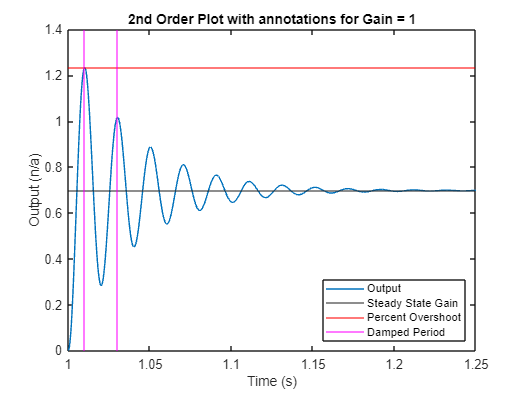

xline(run8.tout(idxs), color='magenta')
legend('Output', 'Steady State Gain', 'Percent Overshoot', 'Damped Period', 'Location', 'southeast')
title('2nd Order Plot with annotations for Gain = 1')
xlabel('Time (s)')
ylabel('Output (n/a)')
hold off

fig9 = figure();
plot(run8.tout, run8.p2)
xlim([1 1.25])
ylim([0 1.75])
hold on
yline(run8.p2(1421))
yline(max(run8.p2), color='red')
idx = find(run8.p2 == max(run8.p2));
xline(run8.tout(idx), color='magenta')
idxs = find(run8.p2(150:1400) == max(run8.p2(150:1400))) + 150;
dampedper = run8.tout(idxs)-run8.tout(idx)

dampedper = 0.0157

percover = 100 * (max(run8.p2) - run8.p2(1421)) / run8.p2(1421)

percover = 81.9109

clgain = run8.p2(1421)

clgain = 0.8214

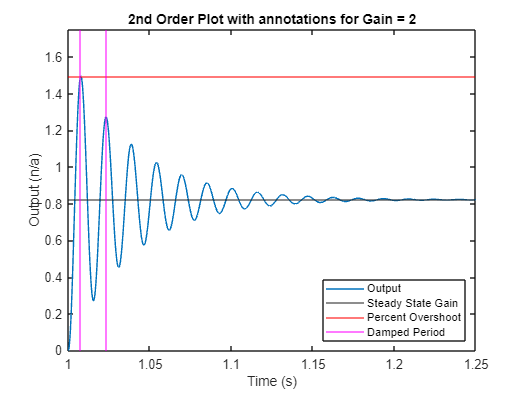

xline(run8.tout(idxs), color='magenta')
legend('Output', 'Steady State Gain', 'Percent Overshoot', 'Damped Period', 'Location', 'southeast')
title('2nd Order Plot with annotations for Gain = 2')
xlabel('Time (s)')
ylabel('Output (n/a)')
hold off